# **WM9QE: Applied Statistics for Artificial Intelligence**

## **Data Sampling **

This MATLAB Live Script is a suppliment to the Data Collection, Sampling, and Synthetic Data session. Full detail of the lectures and examples are availabe on [Section: Week One | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=576666). 

Learning Objectives

- Understand and implement various sampling techniques in MATLAB

- Apply sampling methods to datasets relevant to AI

- Conduct statistical tests to evaluate sampling quality

- Interpret results in the context of AI applications

Overview

This tutorial provides hands-on experience with the data sampling techniques covered in the theoretical session. We will work with two real-world datasets and implement four key sampling strategies:

- Simple Random Sampling (SRS) - Baseline approach for unbiased sampling

- Stratified Sampling - Ensuring representation across all groups

- Cluster Sampling - Sampling natural groupings in data

Note: Two datasets will be used are assumed to be collected via a robust data collection process.

# Section 1: Data Loading and Exploration

## 1.1. Introduction

Before applying any sampling technique, it is essential to thoroughly understand the structure, distribution, and characteristics of your data. Therefore, the first thing to do when working with data is an exploratory phase. It forms the foundation for making informed sampling decisions and interpreting results correctly.

**Why Data Exploration Matters for Sampling**

In AI and machine learning applications, the quality of your training data directly impacts model performance. Poor understanding of data characteristics can lead to:

- **Biased samples** that misrepresent the population

- **Inappropriate sampling strategies** for your data structure

- **Missed opportunities** to leverage natural groupings or stratifications

- **Invalid conclusions** due to undetected data quality issues

Data exploration answers critical questions:

- What is the population size and feature dimensionality?

- Are classes/groups balanced or imbalanced?

- What are the distributions of key variables?

- Are there natural clusters or hierarchical structures?

- What are the baseline population parameters (means, variances)?

## 1.2. Datasets Used in This Tutorial

**1. Fisher's Iris Dataset**

- **Domain:** Botanical classification

- **Size:** 150 observations

- **Features:** 4 continuous measurements (sepal length, sepal width, petal length, petal width)

- **Target:** 3 species classes (setosa, versicolor, virginica)

- **AI Application Context:** This is a classic multi-class classification problem, perfectly balanced with 50 samples per class. It demonstrates sampling challenges when working with structured, labeled data.

- **Why this dataset?** The Iris dataset's perfect class balance allows us to observe how different sampling methods preserve or distort this balance, which is critical for classification tasks.

**2. Patients Medical Dataset**

- **Domain:** Healthcare analytics

- **Size:** 100 observations

- **Features:** 7 variables including demographics (Age, Gender), physical measurements (Height, Weight), vital signs (Systolic/Diastolic blood pressure), and behavioral factors (Smoker status)

- **Mixed data types:** Continuous numerical and categorical variables

- **AI Application Context:** Represents real-world healthcare data used in predictive modeling for patient risk assessment, diagnosis support, and treatment planning.

- **Why this dataset?** The mixed data types and natural groupings (by gender, age ranges) demonstrate how sampling strategies must adapt to different data structures commonly encountered in AI applications.

*To start, let us define all necessary parameters and load the datasets. Parameters can be defined in different ways, but note that all parameters in this tutorial have been defined randomly for illustration purposes only. *

clear all;
clc;
% Performance Evaluation using SE, MOE, and CV
%
% CONFIGURATION NOTE:
% - Using z = 1.96 for MOE calculations (95% confidence interval)
% - For small samples (n < 30), t-distribution is used
% - Missing data: None expected in these datasets
% - Reproducibility: Fixed seed (rng(42))

%% CONFIGURATION: Sampling Parameters
SAMPLE_FRACTION_IRIS = 0.30;        % 30% sample for Iris
SAMPLE_FRACTION_PATIENTS = 0.25;    % 25% sample for Patients
CONFIDENCE_LEVEL = 0.95;             % 95% confidence for MOE
NUM_CLUSTERS_IRIS = 5;               % Number of clusters for Iris
NUM_CLUSTERS_PATIENTS = 4;           % Number of clusters for Patients
CLUSTERS_TO_SELECT_IRIS = 2;         % Clusters to select for Iris
CLUSTERS_TO_SELECT_PATIENTS = 2;     % Clusters to select for Patients

% Set seed for reproducibility
rng('default');
rng(42);

%% SECTION 1.2: Data Loading and Exploration
fprintf('\n========================================\n');

fprintf('SECTION 1: DATA LOADING AND EXPLORATION\n');

SECTION 1: DATA LOADING AND EXPLORATION


fprintf('========================================\n\n');


%%% Load Iris Dataset
fprintf('--- Loading Iris Dataset ---\n');

--- Loading Iris Dataset ---


load fisheriris

iris = array2table(meas, 'VariableNames', ...
    {'SepalLength','SepalWidth','PetalLength','PetalWidth'});
iris.Species = categorical(species);

fprintf('Total samples: %d\n', height(iris));

Total samples: 150


fprintf('Features: %d numerical + 1 categorical\n', width(iris)-1);

Features: 4 numerical + 1 categorical


fprintf('Classes: %d\n\n', numel(categories(iris.Species)));

Classes: 3




iris_numeric_vars = {'SepalLength','SepalWidth','PetalLength','PetalWidth'};

%%% Load Patients Dataset
fprintf('--- Loading Patients Dataset ---\n');

--- Loading Patients Dataset ---


load patients

patients_data = table(Age, Gender, Height, Weight, Systolic, Diastolic, ...
    Smoker, 'VariableNames', ...
    {'Age','Gender','Height','Weight','Systolic','Diastolic','Smoker'});
patients_data.Gender = categorical(patients_data.Gender);
patients_data.Smoker = categorical(string(patients_data.Smoker));

fprintf('Total samples: %d\n', height(patients_data));

Total samples: 100


fprintf('Features: %d\n\n', width(patients_data));

Features: 7




patients_numeric_vars = {'Age','Height','Weight','Systolic','Diastolic'};

Now that the data has been loaded, let's calculate the Standard Error (SE), Margin of Error (MOE) and the Coefficient of Variation (CV), for the original dataset (population).

%%% Compute Original Dataset Metrics
fprintf('--- Original Dataset Metrics ---\n\n');

--- Original Dataset Metrics ---




fprintf('IRIS DATASET (Population):\n');

IRIS DATASET (Population):


iris_original_metrics = compute_dataset_metrics(iris, iris_numeric_vars, ...
    height(iris), height(iris), CONFIDENCE_LEVEL);
display_metrics_table(iris_original_metrics, 'Iris Original');


Iris Original:
Variable                  SE          MOE       CV (%)
-------------------------------------------------------
SepalLength           0.0000       0.0000        14.17
SepalWidth            0.0000       0.0000        14.26
PetalLength           0.0000       0.0000        46.97
PetalWidth            0.0000       0.0000        63.56
-------------------------------------------------------
MEAN                  0.0000       0.0000        34.74



fprintf('\nPATIENTS DATASET (Population):\n');


PATIENTS DATASET (Population):


patients_original_metrics = compute_dataset_metrics(patients_data, ...
    patients_numeric_vars, height(patients_data), height(patients_data), CONFIDENCE_LEVEL);
display_metrics_table(patients_original_metrics, 'Patients Original');


Patients Original:
Variable                  SE          MOE       CV (%)
-------------------------------------------------------
Age                   0.0000       0.0000        18.85
Height                0.0000       0.0000         4.23
Weight                0.0000       0.0000        17.25
Systolic              0.0000       0.0000         5.47
Diastolic             0.0000       0.0000         8.36
-------------------------------------------------------
MEAN                  0.0000       0.0000        10.83


**Built-in MATLAB functions used in the above code snippets:**

- clear

- clc

- rng

- fprintf

- load

- array2table

- categorical

- string

- height

- width

- numel

- categories

**User-defined functions (Helper Functions):**

- compute_dataset_metrics

- display_metrics_table

## 1.3. Exploratoring the Data

Exploring the data is important to help us understand it. Exploratory Data Analysis is ususally performed via Descriptive Statistics or Distribution Analysis. For this tutorial, Distribution Analysis are verified using different plots; following, are some tasks that can be done based on it:

**Task 1: Visualize data distributions to understand:**

- **Shape:** Are variables normally distributed, skewed, or multimodal?

- **Outliers:** Extreme values that might influence sampling

- **Class balance:** Are target categories equally represented?

Understanding distribution shapes informs sampling fraction decisions and helps identify potential issues like class imbalance.

**Task 2: Relationship Exploration**

Examine relationships between variables:

- **Feature correlations:** Which variables move together?

- **Class separability:** How well do features distinguish between classes?

- **Natural groupings:** Are there obvious clusters or strata?

These relationships help identify optimal stratification variables and predict which sampling methods will be most effective.

**Task 3: Data Quality Assessment**

Check for:

- **Missing values:** Gaps that might bias samples

- **Data types:** Ensure categorical and continuous variables are correctly encoded

- **Range validation:** Values within expected bounds

Data quality issues must be addressed before sampling to ensure valid results.

**Interpreting Exploratory Results**

**For the Iris Dataset:**

- **Perfect balance** suggests simple random sampling might work well

- **Clear species separation** (especially for setosa) indicates natural strata

- **Strong feature correlations** (petal length/width) suggest dimensionality reduction opportunities

**For the Patients Dataset:**

- **Continuous age distribution** suggests potential for age-based clustering

- **Gender stratification** ensures both groups are represented

- **Mixed data types** require careful handling in sampling algorithms

**Connecting to Sampling Strategy**

The insights gained from exploration directly inform sampling decisions:

**Best Practices**

- **Always visualize before sampling** – Charts reveal patterns that statistics alone might miss

- **Document population parameters** – These are your ground truth for validation

- **Identify stratification candidates** – Look for categorical variables that create homogeneous groups

- **Consider the AI task** – Classification requires class-balanced samples; regression may prioritize coverage of the feature space

- **Check assumptions** – Many sampling theories assume random processes; verify this holds for your data

With a thorough understanding of our datasets, we can now apply sampling techniques with clear objectives:

- Preserve class distributions (stratified sampling)

- Maintain population parameter estimates (all methods)

- Handle different data scenarios (streaming, distributed, imbalanced)

The exploratory phase establishes the baseline against which we'll measure sampling quality through error and variance metrics in subsequent sections.

%%% 1.3 Exploratory Visualizations
fprintf('\n--- Creating Exploratory Visualizations ---\n');


--- Creating Exploratory Visualizations ---


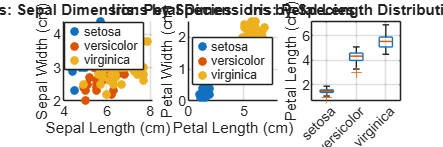


figure('Position', [100 100 1200 400]);
subplot(1,3,1)
gscatter(iris.SepalLength, iris.SepalWidth, iris.Species);
title('Iris: Sepal Dimensions by Species');
xlabel('Sepal Length (cm)'); ylabel('Sepal Width (cm)');
legend('Location', 'best'); grid on;

subplot(1,3,2)
gscatter(iris.PetalLength, iris.PetalWidth, iris.Species);
title('Iris: Petal Dimensions by Species');
xlabel('Petal Length (cm)'); ylabel('Petal Width (cm)');
legend('Location', 'best'); grid on;

subplot(1,3,3)
boxplot(iris.PetalLength, iris.Species);
title('Iris: Petal Length Distribution');
ylabel('Petal Length (cm)'); grid on;

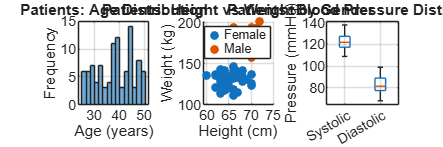


figure('Position', [100 100 1200 400]);
subplot(1,3,1)
histogram(patients_data.Age, 15);
title('Patients: Age Distribution');
xlabel('Age (years)'); ylabel('Frequency'); grid on;

subplot(1,3,2)
gscatter(patients_data.Height, patients_data.Weight, patients_data.Gender);
title('Patients: Height vs Weight by Gender');
xlabel('Height (cm)'); ylabel('Weight (kg)');
legend('Location', 'best'); grid on;

subplot(1,3,3)
boxplot([patients_data.Systolic, patients_data.Diastolic], ...
    'Labels', {'Systolic', 'Diastolic'});
title('Patients: Blood Pressure Distribution');
ylabel('Pressure (mmHg)'); grid on;

**Built-in MATLAB functions:**

- `fprintf`

- `figure`

- `subplot`

- `gscatter`

- `title`

- `xlabel`

- `ylabel`

- `legend`

- `grid`

- `boxplot`

- `histogram`

# Section 2: Simple Random Sampling (SRS)

Simple Random Sampling (SRS) is the most fundamental sampling technique and serves as the baseline against which all other methods are compared. In SRS, every unit in the population has an equal and independent probability of selection.

## **2.1. Mathematical Definition**

For a population of size $N$, each individual unit $i$ has an equal probability of being selected:


$$P(\text{selecting unit } i) = \frac{1}{N} \quad \text{for all } i \in {1, 2, ..., N}$$


This equal probability ensures that the sample mean $\bar{x}$ is an unbiased estimator of the population mean $\mu$:


$$E[\bar{x}] = \mu$$


The variance of the sample mean is:


$$\text{Var}(\bar{x}) = \frac{\sigma^2}{n} \cdot \frac{N-n}{N-1}$$


where $\sigma^2$ is the population variance, and $\frac{N-n}{N-1}$ is the finite population correction (FPC) factor.

However, how much can we trust our sample estimate?

## **2.2. Measuring Estimation Precision: Standard Error (SE)**

SE is the measure of **precision**. It estimates the variability among the means of different samples that could be drawn from the same population. It is the fundamental measure used to calculate the confidence interval, directly quantifying the reliability of the sample mean as an estimate of the population mean.

While SRS is unbiased, each sample produces slightly different estimates due to sampling variability. The Standard Error (SE) quantifies this uncertainty:


$$$$SE(\bar{x}) = \sqrt{\frac{s^2}{n} \cdot \left(\frac{N-n}{N}\right)}$$$$


where:

- $$s^2$$ = sample variance (how spread out the sample is from the mean)

- $$n$$ = sample size (how many observations we collected)

- $$N$$ = population size

- $$\frac{N-n}{N}$$ = finite population correction (FPC)

**Understanding the formula:** The SE tells us the typical distance between our sample mean and the true population mean. Notice that SE decreases as $$n$$ increases (more data = less uncertainty) and as $$s^2$$ decreases as the sampling precision increases (less variable data = more precision).

**Simplified formula:** When the sample is small relative to the population ($$n/N < 0.05$$), the FPC ≈ 1, giving us:


$$$$SE(\bar{x}) \approx \sqrt{\frac{s^2}{n}} = \frac{s}{\sqrt{n}}$$$$


This reveals an important relationship: **to halve the standard error, we need four times the sample size** (since $$\sqrt{4} = 2$$).

## **2.3. Building Confidence: Margin of Error (MOE)**

MOE is the measure of **confidence** (at a specified confidence level). It is a calculated range around the sample estimate. It tells stakeholders, in practical terms, the maximum expected difference between the sample result and the true population value (e.g., *"The result is 55% ± 3%"* or *"I am 95% confident the true mean is between X and Y."*).

The [Margin of Error (MOE)](https://www.qualtrics.com/en-gb/experience-management/research/margin-of-error/) can be defined as:


$$$$MOE = z_{\alpha/2} \times SE(\bar{x})$$$$


Therefore, the MOE scales the SE by a **critical value** $z_{\alpha/2}$ from the standard normal distribution. For common confidence levels, consider:

- 90% confidence: $$z = 1.645$$

- 95% confidence: $$z = 1.96$$

- 99% confidence: $$z = 2.576$$

**Building the confidence interval:**


$$$$\text{True mean } \mu \in [\bar{x} - MOE, \bar{x} + MOE]$$$$


**Interpretation:** We can be 95% confident that this interval contains the true population mean. If we repeated the sampling process 100 times, approximately 95 of those intervals would capture $$\mu$$.

**Example walkthrough:**

## `2.4. `**Checking Sample Representativeness: Variance**

SE and MOE tell us about precision, but we also need to verify that our sample **captures the population's variability correctly**. This is where variance comparison comes in.

- **Population variance** (the true variability we're trying to estimate):


$$$$\sigma^2 = \frac{1}{N} \sum_{i=1}^{N} (x_i - \mu)^2$$$$


- **Sample variance** (our estimate from the sample):


$$$$s^2 = \frac{1}{n-1} \sum_{i=1}^{n} (x_i - \bar{x})^2$$$$


**Note:** We divide by $$n-1$$ (not $$n$$) to make $$s^2$$ an unbiased estimator of $$\sigma^2$$. This [**Bessel's correction**](https://medium.com/analytics-vidhya/explaining-n-1-the-intuition-behind-bessels-correction-for-sample-variance-daee48bd6fde) compensates for the fact that we're using the sample mean $$\bar{x}$$ rather than the true mean $$\mu$$.

**Why this matters:** If $$s^2 \ll \sigma^2$$, our sample is too homogeneous and underestimates population diversity. If $$s^2 \gg \sigma^2$$, our sample may contain outliers or overestimate variability. Ideally, the **variance ratio** should be near 1:


$$$$\text{Variance Ratio} = \frac{s^2}{\sigma^2} \approx 1$$$$


**Example check:**

## `2.5. `**Comparing Across Features: Coefficient of Variation (CV)**

So far, we've analyzed individual features, but how do we compare variability across features with different units and scales? A feature with mean = 100 and std dev = 10 seems more variable than one with mean = 5 and std dev = 1, but is it really?

The **Coefficient of Variation (CV)** solves this by expressing variability relative to the mean:


$$$$CV = \frac{s}{\bar{x}} \times 100%$$$$


where $$s = \sqrt{s^2}$$ is the sample standard deviation.

**Why CV is essential:**

- **Scale-independent:** Removes units, enabling comparison between age (years) and blood pressure (mmHg) for example

- **Relative variability:** Shows whether variation is large or small relative to the typical value

- **Cross-feature comparison:** Identifies which features need more careful sampling

- **Sampling planning:** High CV features may require larger sample sizes for adequate precision

**Interpretation guidelines:**

- **CV < 15%:** Low variability (homogeneous population)

- **CV 15-30%:** Moderate variability

- **CV > 30%:** High variability (heterogeneous population)

**Example comparison:**

## 2.6. The Complete Evaluation Framework

These four metrics work together to provide a comprehensive assessment of sampling quality:

**The storyline:**

- We take a sample → Calculate $$\bar{x}$$ and $$s^2$$

- **Precision:** How reliable is this estimate? → Calculate SE and MOE

- **Representativeness:** Does variability match population? → Check variance ratio

- **Comparison:** Which features need more attention? → Calculate CV

## 2.7. Implementation in Practice

**MATLAB Implementation**

The [`randsample``(n,k)`](https://uk.mathworks.com/help/stats/randsample.html?searchHighlight=randsample&s_tid=srchtitle_support_results_1_randsample#d126e1043124) function implements SRS by:

- Generating random indices from 1 to $N$

- Sampling without replacement (default)

- Ensuring each unit has equal selection probability

**Sampling Fractions Used**

- **Iris Dataset:** 30% (45 out of 150)

- **Patients Dataset:** 25% (25 out of 100)

%% SECTION 2: Simple Random Sampling (SRS)
fprintf('\n\n========================================\n');

fprintf('SECTION 2: SIMPLE RANDOM SAMPLING (SRS)\n');

SECTION 2: SIMPLE RANDOM SAMPLING (SRS)


fprintf('========================================\n\n');


%%% 2.1 Apply SRS to Iris Dataset
fprintf('--- Applying SRS to Iris Dataset (%.0f%%) ---\n', SAMPLE_FRACTION_IRIS*100);

--- Applying SRS to Iris Dataset (30%) ---



sample_size_iris = round(SAMPLE_FRACTION_IRIS * height(iris));
sample_indices_iris = randsample(height(iris), sample_size_iris);
iris_srs = iris(sample_indices_iris, :);

fprintf('Population size: %d\n', height(iris));

Population size: 150


fprintf('Sample size: %d\n\n', sample_size_iris);

Sample size: 45




iris_srs_metrics = compute_dataset_metrics(iris_srs, iris_numeric_vars, ...
    height(iris), height(iris_srs), CONFIDENCE_LEVEL);

fprintf('IRIS SRS - Metrics Comparison:\n');

IRIS SRS - Metrics Comparison:


display_comparison_table(iris_original_metrics, iris_srs_metrics, ...
    'Original', 'SRS');


Variable        | Original (SE/MOE/CV) | SRS (SE/MOE/CV)
--------------------------------------------------------------------------------
SepalLength     | 0.0000 / 0.0000 /  14.2 | 0.1099 / 0.2154 /  15.0
SepalWidth      | 0.0000 / 0.0000 /  14.3 | 0.0631 / 0.1238 /  15.9
PetalLength     | 0.0000 / 0.0000 /  47.0 | 0.2365 / 0.4636 /  51.7
PetalWidth      | 0.0000 / 0.0000 /  63.6 | 0.1020 / 0.1999 /  68.5
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  34.7 | 0.1279 / 0.2507 /  37.8


%%% 2.2 Apply SRS to Patients Dataset
fprintf('\n--- Applying SRS to Patients Dataset (%.0f%%) ---\n', SAMPLE_FRACTION_PATIENTS*100);


--- Applying SRS to Patients Dataset (25%) ---



sample_size_patients = round(SAMPLE_FRACTION_PATIENTS * height(patients_data));
sample_indices_patients = randsample(height(patients_data), sample_size_patients);
patients_srs = patients_data(sample_indices_patients, :);

fprintf('Population size: %d\n', height(patients_data));

Population size: 100


fprintf('Sample size: %d\n\n', sample_size_patients);

Sample size: 25




patients_srs_metrics = compute_dataset_metrics(patients_srs, patients_numeric_vars, ...
    height(patients_data), height(patients_srs), CONFIDENCE_LEVEL);

fprintf('PATIENTS SRS - Metrics Comparison:\n');

PATIENTS SRS - Metrics Comparison:


display_comparison_table(patients_original_metrics, patients_srs_metrics, ...
    'Original', 'SRS');


Variable        | Original (SE/MOE/CV) | SRS (SE/MOE/CV)
--------------------------------------------------------------------------------
Age             | 0.0000 / 0.0000 /  18.8 | 1.2615 / 2.6035 /  19.5
Height          | 0.0000 / 0.0000 /   4.2 | 0.5185 / 1.0700 /   4.5
Weight          | 0.0000 / 0.0000 /  17.3 | 3.9893 / 8.2336 /  15.8
Systolic        | 0.0000 / 0.0000 /   5.5 | 1.5092 / 3.1148 /   7.1
Diastolic       | 0.0000 / 0.0000 /   8.4 | 1.0654 / 2.1988 /   7.4
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  10.8 | 1.6688 / 3.4442 /  10.9


Performing Distribution Analysis can help us better understand the results:

%%% 2.3 Visualizations
fprintf('\n--- Creating SRS Visualizations ---\n');


--- Creating SRS Visualizations ---


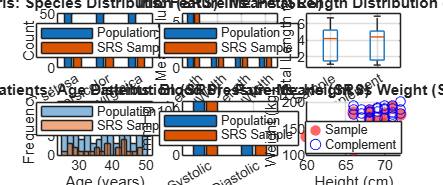


complement_iris = iris(setdiff(1:height(iris), sample_indices_iris), :);
complement_patients = patients_data(setdiff(1:height(patients_data), sample_indices_patients), :);

figure('Position', [100 100 1200 500]);

subplot(2,3,1)
bar([countcats(iris.Species), countcats(iris_srs.Species)]);
legend({'Population','SRS Sample'}, 'Location', 'best');
title('Iris: Species Distribution (SRS)');
xticklabels(categories(iris.Species)); ylabel('Count'); grid on;

subplot(2,3,2)
% Create side-by-side comparison for each feature
feature_means_pop = mean(table2array(iris(:,1:4)));
feature_means_srs = mean(table2array(iris_srs(:,1:4)));
data_iris = [feature_means_pop; feature_means_srs]';
bar(data_iris);
legend({'Population','SRS Sample'}, 'Location', 'best');
title('Iris: Feature Means (SRS)');
xticklabels(iris_numeric_vars); ylabel('Mean Value'); 
xtickangle(45); grid on;

subplot(2,3,3)
boxplot([iris_srs.PetalLength; complement_iris.PetalLength], ...
    [ones(height(iris_srs),1); 2*ones(height(complement_iris),1)], ...
    'Labels', {'Sample','Complement'});
title('Iris: Petal Length Distribution (SRS)');
ylabel('Petal Length (cm)'); grid on;

subplot(2,3,4)
histogram(patients_data.Age, 15, 'FaceAlpha', 0.5); hold on;
histogram(patients_srs.Age, 15, 'FaceAlpha', 0.5);
title('Patients: Age Distribution (SRS)');
xlabel('Age (years)'); ylabel('Frequency');
legend({'Population','SRS Sample'}, 'Location', 'best'); grid on;

subplot(2,3,5)
bp_data = [mean(patients_data.Systolic), mean(patients_data.Diastolic);
           mean(patients_srs.Systolic), mean(patients_srs.Diastolic)]';
bar(bp_data);
legend({'Population','SRS Sample'}, 'Location', 'best');
title('Patients: Blood Pressure Means (SRS)');
xticklabels({'Systolic','Diastolic'}); ylabel('mmHg'); grid on;

subplot(2,3,6)
scatter(patients_srs.Height, patients_srs.Weight, 50, 'r', 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
scatter(complement_patients.Height, complement_patients.Weight, 30, 'b', 'MarkerFaceAlpha', 0.3);
title('Patients: Height vs Weight (SRS)');
xlabel('Height (cm)'); ylabel('Weight (kg)');
legend({'Sample','Complement'}, 'Location', 'best'); grid on;

**Built-in MATLAB functions:**

- `fprintf`

- `round`

- `height`

- `randsample`

- `setdiff`

- `figure`

- `subplot`

- `bar`

- `countcats`

- `legend`

- `title`

- `xticklabels`

- `ylabel`

- `grid`

- `mean`

- `table2array`

- `xtickangle`

- `boxplot`

- `ones`

- `histogram`

- `hold`

- `xlabel`

- `scatter`

**User-defined functions:**

- `compute_dataset_metrics`

- `display_comparison_table`

## 2.8. Interpreting Your Results

**What to Look For:**

- **Error Magnitude**: Are errors small relative to feature scales?

- **Error Pattern**: Are errors randomly distributed or systematically biased?

- **Variance Similarity**: Do sample variances approximate population variances?

- **Visual Inspection**: Do histograms and distributions look similar?

- **Class Balance**: Are all categories adequately represented?

**Red Flags:**

- **Large systematic bias** in one direction → Check random seed or sampling function

- **Missing classes** in sample → Sample size too small or use stratified sampling

- **Highly different variances** → Potential outliers or sampling issues

- **Non-random patterns** in errors → Verify true randomness of selection

**Class Distribution in SRS:**

The Minority Class Problem: In SRS, class proportions are not guaranteed to match population proportions. For Iris:

- Population: 33.3% per species

- SRS sample: Can vary (e.g., 28%-36%-36%)

**Why this matters for AI:**

- Training on imbalanced samples can bias classifiers

- Minority classes may be underrepresented or missing entirely

- Model performance metrics become unreliable

**When is this problematic?**

- Small sample sizes relative to number of classes

- Naturally imbalanced populations (fraud detection: 1% fraud cases)

- Cost-sensitive applications where minority class is critical

## 2.9. Worked example: A complete analysis by hand

## **2.10. Key Insights**

**Understanding the calculation flow:**

- **Population level:** Calculate μ and σ² from all N observations (ground truth)

- **Sample level:** Calculate x̄ and s² from n selected observations (estimates)

- **Precision metrics:** Use sample statistics to quantify uncertainty (SE, MOE)

- **Quality checks:** Compare sample to population (variance ratio, CV)

**Standard Error and sample size relationship (for the Worked Example above):**

- Current: $n = 45$, $SE = 0.225 cm$ 

- To halve SE: Need $n = 180 $ (4× larger) 

- To reduce SE by 70%: Need $n = 150$ (3.3× larger) 

This demonstrates the **diminishing returns** of increasing sample size: large improvements require substantial additional sampling.

**When variance ratio deviates from 1:**

- Ratio < 0.8: Sample too homogeneous (may have missed extremes)

- Ratio > 1.2: Sample too heterogeneous (possible outliers or sampling error)

- Check for: Measurement errors, sampling procedure issues, population structure

**CV guides sampling strategy:**

- Low CV (<15%): Standard sample sizes sufficient

- High CV (>30%): Consider larger samples OR stratification

- Very high CV (>50%): Population likely has subgroups → use stratified sampling

**Key Takeaways:**

- Population parameters ($\mu , \sigma ²$) are calculated from ALL observations using ($1/N$)

- Sample statistics ($x̄, s²$) are calculated from selected observations using ($1/n$) for mean, ($1/(n-1)$) for variance

- SE quantifies how far $x̄$ typically is from $\mu $; smaller SE means more reliable estimates

- MOE builds confidence intervals from SE; narrower intervals indicate better precision

- Variance comparison ($s²/\sigma ²$) validates that sample captures population spread correctly

- CV enables fair comparison across features with different scales

- Together, these metrics provide objective evaluation of SRS quality

- High CV signals need for either larger samples or stratified sampling approaches

## 2.11. Practical Recommendations

When to Use SRS:

✓ Exploratory data analysis and initial prototyping

✓ Balanced datasets with no obvious strata

✓ When simplicity and interpretability are priorities

✓ As a baseline for comparing other methods

✓ When population structure is unknown

**When to Consider Alternatives:**

✗ Imbalanced classification problems (use stratified sampling)

✗ Naturally clustered data (use cluster sampling)

✗ Streaming data (use reservoir sampling)

✗ Known heterogeneous variance across groups (use stratified sampling)

✗ Cost of sampling varies by subgroup (use optimal allocation)

# Section 3: Stratified Sampling

Stratified sampling is a probability sampling technique that divides the population into homogeneous subgroups called **strata** (singular: stratum), then samples independently from each stratum. This approach guarantees representation from all subgroups and often produces more precise estimates than simple random sampling.

## **3.1. Mathematical Definition**

For a population of size $N
$ divided into $L$ strata:


$$N = \sum_{h=1}^{L} N_h$$


where $N_h$ is the size of stratum $h$.

In proportional allocation, the sample size from each stratum maintains population proportions:


$$n_h = n \cdot \frac{N_h}{N}$$


where $n$ is the total sample size.

**Stratified Mean Estimator**

The stratified sample mean is a weighted average of stratum means:


$$x_{\textrm{st}} =\sum_{h=1}^L W_h {\bar{x} }_h$$


where $W_h = N_h / N$ is the stratum weight and $\bar{x}_h$ is the sample mean in stratum $h$.

**Key advantage:** Unlike SRS, stratified sampling **guarantees** that all subgroups are represented proportionally, eliminating the risk of missing minority classes.

**Why Stratified Sampling Reduces Variance**

The defining feature of stratified sampling is variance reduction compared to SRS. This occurs because we eliminate between-stratum variance from the sampling error.

**Intuition:** If strata are internally homogeneous (low within-stratum variance) but different from each other (high between-stratum variance), sampling from each separately is more efficient than random sampling from the mixed population.

**Theoretical result:**


$$$$\text{Var}(\bar{x}{st}) \leq \text{Var}(\bar{x}{SRS})$$$$


The variance reduction is maximized when:

- Strata are **homogeneous within** (observations similar to each other)

- Strata are **heterogeneous between** (strata differ from each other)

**Example:** In the Iris dataset, stratifying by species creates homogeneous groups (each species has similar petal lengths) that differ substantially from each other (setosa has short petals, virginica has long petals).

## **3.2. Standard Error (SE) for Stratified Sampling**

The Standard Error for stratified sampling reflects this variance reduction:


$$SE(\bar{x} st)=\sqrt{\sum_{h=1}^L W_h^2 \cdot \frac{s_h^2 }{n_h }\cdot \left(1-\frac{n_h }{N_h }\right)}$$


where:

- $$W_h = N_h / N$$ is the stratum weight

- $$s_h^2$$ is the sample variance in stratum $$h$$

- $$n_h$$ is the sample size in stratum $$h$$

- $$N_h$$ is the population size in stratum $$h$$

**Understanding the formula:** Unlike SRS which has a single variance term, stratified sampling sums the contributions from each stratum. Each stratum contributes according to:

- Its **weight** $$W_h^2$$ (larger strata contribute more)

- Its **within-stratum variance** $$s_h^2$ $(more variable strata contribute more uncertainty)

- Its **sampling fraction** through the FPC term

**Simplified form** (when $$n_h/N_h$$ is small):


$$SE(\bar{x} st)\approx \sqrt{\sum_{h=1}^L W_h^2 \cdot \frac{s_h^2 }{n_h }}$$


**Comparing to SRS:** If all strata have the same mean (making stratification pointless), this formula reduces to the SRS formula. Otherwise, $$SE_{st} < SE_{SRS}$$.

## **3.3. Margin of Error (MOE) for Stratified Sampling**

The Margin of Error follows the same logic as SRS, but uses the stratified SE:


$$$$MOE_{st} = z_{\alpha/2} \times SE(\bar{x}_{st})$$$$


For 95% confidence, $$z = 1.96$$, giving the confidence interval:


$$$$\mu \in [\bar{x}{st} - MOE{st}, \bar{x}{st} + MOE{st}]$$$$


**Expected result:** Since $$SE_{st} < SE_{SRS}$$, we also get $$MOE_{st} < MOE_{SRS}$$, meaning **narrower confidence intervals** and more precise estimates.

## 3.4. Variance Analysis in Stratified Sampling

Overall Variance Comparison: We compare the stratified sample variance to the population variance:


$$$$s_{st}^2 = \sum_{h=1}^{L} W_h s_h^2 + \sum_{h=1}^{L} W_h (\bar{x}h - \bar{x}{st})^2$$$$


This is the **within-stratum variance** plus **between-stratum variance** in the sample.

**Variance Ratio:**


$$$$\text{Variance Ratio} = \frac{s_{st}^2}{\sigma^2} \approx 1$$$$


**Interpretation:** Like SRS, the overall sample variance should approximate the population variance. The difference is that stratified sampling achieves this while also ensuring proportional representation.

**Within-Stratum Analysis**

A unique advantage of stratified sampling is examining variance **within each stratum**:


$$$$\text{Stratum Variance Ratio}_h = \frac{s_h^2}{\sigma_h^2}$$$$


This checks whether each stratum's sample captures its own population variance correctly.

**Why this matters:**

- Identifies problematic strata (where sample is unrepresentative)

- Validates homogeneity assumption (low $$s_h^2$$ confirms stratum is homogeneous)

- Helps decide if further stratification needed

## 3.5. Proportional Representation: The Defining Feature

The **key distinction** of stratified sampling is **perfect preservation** of population proportions:


$$$$\frac{n_h}{n} = \frac{N_h}{N} \quad \text{exactly}$$$$


**Verification metric:**


$$$$\text{Proportion Difference}_h = \left| \frac{n_h}{n} - \frac{N_h}{N} \right|$$$$


**For valid stratified sampling:** This difference should be **exactly 0** for all strata (within rounding error).

**Contrast with SRS:**

- SRS: Proportions approximate but not guaranteed (e.g., 15-13-17 instead of 15-15-15)

- Stratified: Proportions exact by design (always 15-15-15 if sampling 30% from each)

**Why critical for AI:**

- Classification models require balanced training data

- Minority classes guaranteed adequate representation

- Fairness requirements satisfied by design

- Model evaluation metrics more reliable

## 3.6. Coefficient of Variation (CV) for Stratified Sampling

The CV calculation remains the same as SRS:


$$$$CV = \frac{s}{\bar{x}_{st}} \times 100%$$$$


where $$s = \sqrt{s_{st}^2}$$ is the overall sample standard deviation.

**Stratified sampling typically shows lower CV** when stratification is effective, because we've reduced the overall variance by eliminating between-stratum variation from sampling error.

**Per-stratum CV** can also be calculated:


$$$$CV_h = \frac{s_h}{\bar{x}_h} \times 100%$$$$


**Interpretation:** Comparing $$CV_h$$ across strata identifies which subgroups are more variable and might need larger sample sizes.

## **3.7. Efficiency Gain: Design Effect (DEFF)**

The DEFF quantifies efficiency relative to SRS:


$$$$\text{DEFF}{st} = \frac{\text{Var}(\bar{x}{st})}{\text{Var}(\bar{x}{SRS})} = \frac{SE{st}^2}{SE_{SRS}^2}$$$$


**Interpretation:**

- $$\text{DEFF}_{st} < 1$$: Stratified is MORE efficient than SRS

- $$\text{DEFF}_{st} = 0.5$$: Stratified achieves same precision as SRS with half the variance

- Typical values: 0.5 to 0.9 (10-50% variance reduction)

**Equivalent sample size:** A stratified sample of size $$n$$ has the same precision as an SRS of size $$n / \text{DEFF}_{st}$$.

Example: If DEFF = 0.7, then $$n = 100$$ stratified observations provide the same precision as $$n = 143$$ SRS observations.

## 3.8. Choosing Stratification Variables

Good Stratification Variables Should:

- **Create homogeneous strata**: Low variance within each stratum

- **Be categorical or easily categorized**: Species, gender, age groups, regions

- **Be known for entire population**: Available before sampling

- **Have theoretical/practical relevance**: Related to outcome of interest

- **Have sufficient size per stratum**: Each stratum needs adequate $n_h$

**For Our Datasets:**

**Iris Dataset: Stratify by Species**

- Creates three natural strata (setosa, versicolor, virginica)

- Species is the target variable for classification

- Each species has distinct characteristics (homogeneous within)

- Perfectly balanced population (50 per species)

**Patients Dataset: Stratify by Gender**

- Creates two natural strata (Male, Female)

- Gender affects many health outcomes (heterogeneous between)

- Important for fairness in healthcare AI

- Relatively balanced population

**Alternative Stratification Options:**

**Iris:** Could stratify by petal size ranges, but species is more meaningful for classification

**Patients:** Could stratify by:

- Age groups (young, middle, mature, senior)

- Smoker status (yes/no)

- Combined gender × age (multi-way stratification)

## 3.9. The Complete Evaluation Framework

Now, let's apply some of the above concepts to both datasets:

%% SECTION 3: Stratified Sampling
fprintf('\n\n========================================\n');

fprintf('SECTION 3: STRATIFIED SAMPLING\n');

SECTION 3: STRATIFIED SAMPLING


fprintf('========================================\n\n');


%%% 3.1 Apply Stratified Sampling to Iris (by Species)
fprintf('--- Applying Stratified Sampling to Iris (%.0f%% per stratum) ---\n', ...
    SAMPLE_FRACTION_IRIS*100);

--- Applying Stratified Sampling to Iris (30% per stratum) ---



iris_stratified = table();
species_categories = categories(iris.Species);

fprintf('Stratification Plan:\n');

Stratification Plan:


fprintf('%-15s %12s %12s %12s\n', 'Stratum', 'Pop Size', 'Sample Size', 'Fraction');

Stratum             Pop Size  Sample Size     Fraction


fprintf('%s\n', repmat('-', 1, 55));

-------------------------------------------------------



for i = 1:numel(species_categories)
    stratum = species_categories{i};
    stratum_data = iris(iris.Species == stratum, :);
    stratum_size = height(stratum_data);
    sample_size = round(SAMPLE_FRACTION_IRIS * stratum_size);
    stratum_indices = randsample(stratum_size, sample_size);
    iris_stratified = [iris_stratified; stratum_data(stratum_indices, :)];
    fprintf('%-15s %12d %12d %11.1f%%\n', stratum, stratum_size, sample_size, ...
        (sample_size/stratum_size)*100);
end

setosa                    50           15        30.0%
versicolor                50           15        30.0%
virginica                 50           15        30.0%



fprintf('\nTotal sample size: %d\n\n', height(iris_stratified));


Total sample size: 45




iris_stratified_metrics = compute_stratified_metrics(iris, iris_stratified, ...
    iris_numeric_vars, 'Species', CONFIDENCE_LEVEL);

fprintf('IRIS STRATIFIED - Metrics Comparison:\n');

IRIS STRATIFIED - Metrics Comparison:


display_comparison_table(iris_original_metrics, iris_stratified_metrics, ...
    'Original', 'Stratified');


Variable        | Original (SE/MOE/CV) | Stratified (SE/MOE/CV)
--------------------------------------------------------------------------------
SepalLength     | 0.0000 / 0.0000 /  14.2 | 0.0666 / 0.1306 /  14.7
SepalWidth      | 0.0000 / 0.0000 /  14.3 | 0.0480 / 0.0940 /  13.8
PetalLength     | 0.0000 / 0.0000 /  47.0 | 0.0430 / 0.0843 /  47.5
PetalWidth      | 0.0000 / 0.0000 /  63.6 | 0.0252 / 0.0494 /  63.6
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  34.7 | 0.0457 / 0.0896 /  34.9



fprintf('\n--- Proportional Representation Check ---\n');


--- Proportional Representation Check ---


fprintf('%-15s %15s %15s %15s\n', 'Species', 'Pop Prop', 'Sample Prop', 'Difference');

Species                Pop Prop     Sample Prop      Difference


fprintf('%s\n', repmat('-', 1, 62));

--------------------------------------------------------------


pop_props = countcats(iris.Species) / height(iris);
sample_props = countcats(iris_stratified.Species) / height(iris_stratified);
for i = 1:numel(species_categories)
    diff = abs(pop_props(i) - sample_props(i));
    fprintf('%-15s %15.4f %15.4f %15.6f\n', species_categories{i}, ...
        pop_props(i), sample_props(i), diff);
end

setosa                   0.3333          0.3333        0.000000
versicolor               0.3333          0.3333        0.000000
virginica                0.3333          0.3333        0.000000


%%% 3.2 Apply Stratified Sampling to Patients (by Gender)
fprintf('\n\n--- Applying Stratified Sampling to Patients (%.0f%% per stratum) ---\n', ...
    SAMPLE_FRACTION_PATIENTS*100);



--- Applying Stratified Sampling to Patients (25% per stratum) ---



patients_stratified = table();
gender_categories = categories(patients_data.Gender);

fprintf('Stratification Plan:\n');

Stratification Plan:


fprintf('%-10s %12s %12s %12s\n', 'Stratum', 'Pop Size', 'Sample Size', 'Fraction');

Stratum        Pop Size  Sample Size     Fraction


fprintf('%s\n', repmat('-', 1, 50));

--------------------------------------------------



for i = 1:numel(gender_categories)
    stratum = gender_categories{i};
    stratum_data = patients_data(patients_data.Gender == stratum, :);
    stratum_size = height(stratum_data);
    sample_size = round(SAMPLE_FRACTION_PATIENTS * stratum_size);
    stratum_indices = randsample(stratum_size, sample_size);
    patients_stratified = [patients_stratified; stratum_data(stratum_indices, :)]; %#ok<AGROW>
    fprintf('%-10s %12d %12d %11.1f%%\n', stratum, stratum_size, sample_size, ...
        (sample_size/stratum_size)*100);
end

Female               53           13        24.5%
Male                 47           12        25.5%



fprintf('\nTotal sample size: %d\n\n', height(patients_stratified));


Total sample size: 25




patients_stratified_metrics = compute_stratified_metrics(patients_data, ...
    patients_stratified, patients_numeric_vars, 'Gender', CONFIDENCE_LEVEL);

fprintf('PATIENTS STRATIFIED - Metrics Comparison:\n');

PATIENTS STRATIFIED - Metrics Comparison:


display_comparison_table(patients_original_metrics, patients_stratified_metrics, ...
    'Original', 'Stratified');


Variable        | Original (SE/MOE/CV) | Stratified (SE/MOE/CV)
--------------------------------------------------------------------------------
Age             | 0.0000 / 0.0000 /  18.8 | 1.2712 / 2.6235 /  19.3
Height          | 0.0000 / 0.0000 /   4.2 | 0.3199 / 0.6603 /   4.0
Weight          | 0.0000 / 0.0000 /  17.3 | 1.5941 / 3.2900 /  18.3
Systolic        | 0.0000 / 0.0000 /   5.5 | 1.0654 / 2.1988 /   5.1
Diastolic       | 0.0000 / 0.0000 /   8.4 | 1.2060 / 2.4891 /   9.0
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  10.8 | 1.0913 / 2.2523 /  11.1


Now, we can perform the Distribution Analysis:

%%% 3.3 Visualizations
fprintf('\n--- Creating Stratified Sampling Visualizations ---\n');


--- Creating Stratified Sampling Visualizations ---


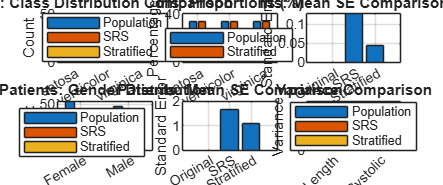


figure('Position', [100 100 1200 500]);

subplot(2,3,1)
bar([countcats(iris.Species), countcats(iris_srs.Species), ...
     countcats(iris_stratified.Species)]);
legend({'Population','SRS','Stratified'}, 'Location', 'best');
title('Iris: Class Distribution Comparison');
xticklabels(species_categories); ylabel('Count'); grid on;

subplot(2,3,2)
proportions_comp = [pop_props, sample_props] * 100;
bar(proportions_comp);
legend({'Population','Stratified'}, 'Location', 'best');
title('Iris: Proportions (%)');
xticklabels(species_categories); ylabel('Percentage'); grid on;

subplot(2,3,3)
se_comparison = [iris_original_metrics.SE_Mean; 
                 iris_srs_metrics.SE_Mean; 
                 iris_stratified_metrics.SE_Mean];
bar(se_comparison);
title('Iris: Mean SE Comparison');
xticklabels({'Original','SRS','Stratified'});
ylabel('Standard Error'); grid on; 

subplot(2,3,4)
bar([countcats(patients_data.Gender), countcats(patients_srs.Gender), ...
     countcats(patients_stratified.Gender)]);
legend({'Population','SRS','Stratified'});
title('Patients: Gender Distribution');
xticklabels(gender_categories); ylabel('Count'); grid on;

subplot(2,3,5)
se_comparison_patients = [patients_original_metrics.SE_Mean; 
                          patients_srs_metrics.SE_Mean; 
                          patients_stratified_metrics.SE_Mean];
bar(se_comparison_patients);
title('Patients: Mean SE Comparison');
xticklabels({'Original','SRS','Stratified'});
ylabel('Standard Error'); grid on;

subplot(2,3,6)
var_comparison = [var(iris.PetalLength), var(iris_srs.PetalLength), var(iris_stratified.PetalLength);
                  var(patients_data.Systolic), var(patients_srs.Systolic), var(patients_stratified.Systolic)];
bar(var_comparison);
legend({'Population','SRS','Stratified'}, 'Location', 'best');
title('Variance Comparison');
xticklabels({'Iris: Petal Length','Patients: Systolic'}); 
ylabel('Variance'); xtickangle(45); grid on;

**Built-in MATLAB functions:**

- `fprintf`

- `categories`

- `table`

- `repmat`

- `numel`

- `round`

- `randsample`

- `height`

- `abs`

- `countcats`

- `figure`

- `subplot`

- `bar`

- `legend`

- `title`

- `xticklabels`

- `ylabel`

- `grid`

- `var`

- `xtickangle`

**User-defined functions:**

- `compute_stratified_metrics`

- `display_comparison_table`

## 3.10. Interpreting Your Results

**What to Look For:**

- **Perfect Proportions**: Class distribution exactly matches population

- **Reduced Errors**: MAE and MSE lower than SRS baseline

- **Lower Variance**: Especially for features correlated with stratification variable

- **Consistent Within-Stratum Estimates**: Small errors in each stratum separately

- **Adequate Stratum Sample Sizes**: Each $n_h \geq 30$ ideally (for normality)

**Success Indicators:**

✓ **Proportional representation difference < 0.001** (essentially zero)

✓ **No missing classes** in any stratum

✓ **Variance ratio < 1** for highly stratified features

✓ **Similar or better** performance on all metrics vs. SRS

**Red Flags:**

- **Proportions don't match exactly** → Implementation error, check stratum sampling

- **One stratum has huge errors** → Stratum may need subdivision or larger $$n_h$$

- **No improvement over SRS** → Poor stratification choice, strata may not be homogeneous

- **Empty strata in sample** → Total $$n$$ too small or allocation error

- **Higher variance than SRS** → Should never happen with proportional allocation; check code

## 3.11. Worked example: A complete analysis by hand

## **3.12. Key Insights**

**Understanding the variance decomposition:**

- Total variance = Within-stratum variance + Between-stratum variance

- SRS experiences both components as sampling error

- Stratified sampling eliminates between-stratum variance from error

- Efficiency gain proportional to between-stratum variance

**Why this example shows exceptional gains:**

- **High between-stratum variance:** Species differ dramatically (CV=47% overall but <15% within)

- **Low within-stratum variance:** Each species homogeneous

- **Perfect stratification variable:** Species is the causal factor for petal length

- **Equal stratum sizes:** Simplifies allocation and increases efficiency

**Practical interpretation:**

- Stratified sample (n=45) has same precision as SRS (n≈882)

- Could reduce sample size by 95% while maintaining precision

- Or maintain sample size but reduce SE by 77%

- Perfect for imbalanced classification (guarantees minority class samples)

**When stratification works best:**

- Stratification variable strongly correlated with outcome

- Strata internally homogeneous (low within-stratum CV)

- Strata externally heterogeneous (different means between strata)

- Known population proportions for each stratum

**When stratification provides minimal gain:**

- Strata have similar means (little between-stratum variance)

- Strata internally heterogeneous (high within-stratum variance)

- Poor choice of stratification variable (uncorrelated with outcome)

- Result: DEFF ≈ 1 (no better than SRS)

**Key Takeaways:**

- Stratified sampling guarantees exact proportional representation (impossible with SRS)

- Variance reduction achieved by eliminating between-stratum variance from sampling error

- SE and MOE are substantially lower than SRS when stratification is effective

- Design Effect quantifies efficiency gain (DEFF < 1 is better than SRS)

- Within-stratum CV should be low (<15%) to confirm homogeneity assumption

- Perfect for imbalanced classification problems in AI/ML

- Most effective when stratification variable is causal or highly correlated with outcome

- For Iris petal length stratified by species: 77% SE reduction, 19.6× more efficient than SRS

## 3.13. Practical Recommendations

**When to Use Stratified Sampling:**

✓ **Classification tasks** with categorical outcomes

✓ **Imbalanced datasets** where minority classes are critical

✓ **Subgroup analysis** is required or anticipated

✓ **Fairness constraints** require demographic representation

✓ **Known population structure** with clear stratification variables

✓ **High variance** between groups, low variance within groups

✓ **Multi-site studies** with natural geographical strata

**When SRS Might Be Preferable:**

✗ Balanced datasets with no clear strata

✗ Unknown population structure

✗ Very small sample sizes (stratification overhead not justified)

✗ Continuous outcomes with no obvious categorical groupings

✗ Exploratory research where stratification choice is unclear

# Section 4: Cluster Sampling

Cluster sampling divides the population into natural groupings called clusters, randomly selects a subset of clusters, and includes all units within the selected clusters in the samples.

## **4.1. Mathematical Definition**

For a population divided into $C$ clusters:


$$N = \sum_{i=1}^{C} N_i$$


where $N_i$ is the size of cluster $i$.

In single-stage cluster sampling, we:

- Randomly select $c$ clusters from the $C$ total clusters

- Include all $N_i$ units from each selected cluster

- Total sample size: $n = \sum_{i \in \text{selected}} N_i$

**Cluster Mean Estimator**

The cluster sample mean is:


$$\bar{x_{\textrm{cl}} \;} =\frac{\sum_{i\in \textrm{selected}} \sum_{j=1}^{N_i } x_{\textrm{ij}} }{\sum_{i\in \textrm{selected}} N_i }$$


For equal-sized clusters ($N_i = \bar{N}$), this simplifies to:


$$\bar{x} cl=\frac{1}{c}\sum_{i\in \textrm{selected}} {\bar{x} }_i$$


where $\bar{x}_i$ is the mean of cluster $i$.

**Critical distinction from stratified sampling (Single-Stage Cluster Sampling):** We sample SOME clusters (not all) and include ALL units in selected clusters (not some).

## **4.2. Variance of Cluster Estimator**

Unlike stratified sampling which reduces variance, cluster sampling typically increases variance compared to SRS. This occurs because we rely on a subset of clusters to represent all clusters.

**The key issue:** If selected clusters happen to be atypical, our estimates will be biased. The variance depends on how much clusters differ from each other (**between-cluster** variation):


$$\text{Var}(\bar{x}_{cl}) = \left(1 - \frac{c}{C}\right) \frac{\sigma_b^2}{c}$$


where $\sigma_b^2$ is the **between-cluster variance**:


$$\sigma_b^2 = \frac{1}{C-1} \sum_{i=1}^{C} (\bar{x}_i - \mu)^2$$


**Critical insight:** Variance is driven by differences between cluster means, not within-cluster variation.

**Understanding the formula:** Variance increases when:

- **Few clusters selected** ($c$ small relative to $C$) 

- **High between-cluster variance** (cluster means differ substantially)

- **Clusters are homogeneous within** (observations in same cluster are similar)

**Contrast with stratified sampling:**

- **Stratified:** Sample ALL strata (eliminates between-stratum variance)

- **Cluster:** Sample SOME clusters (between-cluster variance remains as sampling error)

### **4.2.1. Intracluster Correlation Coefficient (ICC)**

The ICC measures similarity within clusters, that is, how similar units within the same cluster are:


$$\rho = \frac{\sigma_b^2}{\sigma_b^2 + \sigma_w^2}$$


where:

- $\sigma_b^2$ = between-cluster variance

- $\sigma_w^2$ = within-cluster variance

- 
$$\rho \in [0, 1]$$


**Interpretation:**

- $\rho = 0$: No clustering effect (units within clusters are no more similar than random)

- $\rho = 1$: Perfect clustering (all units in a cluster are identical)

- $\rho > 0$: Positive correlation increases design effect

**Why ICC matters:** Higher ICC means:

- Less information per observation (redundancy within clusters)

- Greater design effect (lower efficiency)

- Need more clusters or larger sample to achieve same precision as SRS

**Ideal for cluster sampling:** $$\rho \approx 0$$ (clusters are "mini-populations" representing full diversity) 

**Problematic:** $\rho >0.1$ (substantial loss of efficiency)

## **4.3. Design Effect (DEFF) for Cluster Sampling**

The DEFF measures efficiency loss compared to SRS:


$$\text{DEFF}_{cl} = 1 + (m - 1)\rho$$


where $m$ is the average cluster size.

**Key insight:**

- Unlike stratified sampling where DEFF < 1, cluster sampling typically has **DEFF > 1**

- Therefore, cluster sampling is **less efficient** than SRS

- Efficiency decreases as cluster size and ICC increase

**Understanding the formula:**

- If $\rho =0$ (no clustering): DEFF = 1 (same efficiency as SRS) 

- If $\rho > 0$: DEFF > 1 (less efficient, increases with cluster size) 

- Larger clusters make DEFF worse when $\rho > 0$

**Examples:**

- $\rho = 0.05$, $m=50$: DEFF = 1 + (49)(0.05) = 3.45 

- $\rho = 0.10$, $m=50$: DEFF = 1 + (49)(0.10) = 5.90 

**Interpretation:** DEFF = 3.45 means cluster sample has only 29% (1/3.45) of the statistical efficiency of an SRS of the same size. To match SRS precision, you'd need 3.45× larger sample.

**Economic justification:** Use cluster sampling when cost savings exceed statistical efficiency loss.

## 4.4 Standard Error (SE) for Cluster Sampling

The SE for cluster sampling reflects the increased variance:


$$$$SE(\bar{x}_{cl}) = \sqrt{\left(1 - \frac{c}{C}\right) \cdot \frac{s_b^2}{c}}$$$$


where $$s_b^2$$ is the sample estimate of between-cluster variance:


$$$$s_b^2 = \frac{1}{c-1} \sum_{i \in \text{selected}} (\bar{x}i - \bar{x}{cl})^2$$$$


**Simplified interpretation:** SE depends primarily on:

- **Number of clusters selected** ($$c$$) - more clusters → lower SE

- **Variability between cluster means** ($$s_b^2$$) - more variable → higher SE

**Critical observation:** SE depends on number of **clusters** sampled, not total number of **units**. Adding more units to same clusters provides diminishing returns.

**Relationship to SRS:**


$$$$SE_{cl} \approx SE_{SRS} \times \sqrt{\text{DEFF}}$$$$


When DEFF = 4, cluster sampling SE is 2× larger than SRS SE for the same total sample size.

## 4.5. Margin of Error (MOE) for Cluster Sampling

The Margin of Error follows the standard approach:


$$$$MOE_{cl} = t_{\alpha/2, c-1} \times SE(\bar{x}_{cl})$$$$


**Important:** We use the t-distribution with $$c-1$$ degrees of freedom (not $$n-1$$) because the effective sample size is the number of clusters, not units.

For 95% confidence with few clusters:

- $$c = 5$$: $$t_{0.025, 4} = 2.776$$

- $$c = 10$$: $$t_{0.025, 9} = 2.262$$

- $$c = 30$$: $$t_{0.025, 29} = 2.045$$ (approaching $$z = 1.96$$)

The confidence interval is:


$$$$\mu \in [\bar{x}{cl} - MOE{cl}, \bar{x}{cl} + MOE{cl}]$$$$


**Expected result:** Wider confidence intervals than SRS or stratified due to higher SE and sometimes higher critical value.

## **4.6. Variance Analysis in Cluster Sampling**

**Between-Cluster vs. Within-Cluster Variance**

The total population variance decomposes as:


$$$$\sigma^2 = \sigma_w^2 + \sigma_b^2$$$$


**Sample estimates:**


$$$$s_w^2 = \frac{1}{n - c} \sum_{i \in \text{selected}} \sum_{j=1}^{N_i} (x_{ij} - \bar{x}_i)^2$$$$



$$$$s_b^2 = \frac{1}{c-1} \sum_{i \in \text{selected}} N_i(\bar{x}i - \bar{x}{cl})^2$$$$


**Interpretation:**

- **High **$$s_w^2$$**, low **$$s_b^2$$: Good for cluster sampling (clusters are similar, each represents population)

- **Low **$$s_w^2$$**, high **$$s_b^2$$: Bad for cluster sampling (clusters differ, selected clusters may be unrepresentative)

**Estimated ICC from sample:**


$$$$\hat{\rho} = \frac{s_b^2}{s_b^2 + s_w^2}$$$$


**Coverage Analysis**

Unlike stratified sampling which guarantees representation, cluster sampling can have **coverage gaps**:

**Range coverage:**


$$$$\text{Coverage} = \frac{\max(\text{sample}) - \min(\text{sample})}{\max(\text{population}) - \min(\text{population})} \times 100%$$$$


**Subgroup representation:** Check if all important subgroups present in selected clusters.

**Why this matters:** Missing clusters may contain unique characteristics not represented in sample, leading to biased estimates.

## 4.7 Coefficient of Variation (CV)

The CV calculation follows the standard formula:


$$$$CV = \frac{s}{\bar{x}_{cl}} \times 100%$$$$


Per-cluster CV can identify heterogeneous clusters:


$$$$CV_i = \frac{s_i}{\bar{x}_i} \times 100%$$$$


**Ideal scenario:** All clusters have similar CVs (confirms clusters are "mini-populations")

**Warning sign:** Large variation in cluster CVs suggests some clusters are very different from others.

## 4.8. The Complete Evaluation Framework

**Success criteria depend on context:**

- If cost savings are 10×, DEFF = 5 may be acceptable

- If precision is critical, DEFF > 2 may be unacceptable

- Must balance statistical efficiency against practical feasibility

## 4.9. Cluster Sampling in This Tutorial

**Iris Dataset: Petal Length-Based Clusters**

**Cluster definition:**

- Divide iris data into 5 clusters based on petal length ranges

- Each cluster represents a range of petal lengths

- Randomly select 2 of the 5 clusters

**Why this clustering? **Petal length is highly correlated with species:

- Cluster 1: Mostly setosa (short petals)

- Clusters 2-3: Mixed or versicolor

- Clusters 4-5: Mostly virginica (long petals)

**Expected outcome:**

- High between-cluster variance (different species dominate different clusters)

- Selected clusters will be unrepresentative of full population

- Species distribution will be skewed

**Purpose:** Demonstrates the **bias risk** when clusters are heterogeneous between but homogeneous within.

**Patients Dataset: Age-Based Clusters**

**Cluster definition:**

- Four age groups: Young (0-29), Middle (30-44), Mature (45-59), Senior (60+)

- Randomly select 2 of the 4 clusters

**Why this clustering?**Age is associated with health outcomes:

- Different age groups have different blood pressure, weight profiles

- Each cluster has distinct characteristics

**Expected outcome:**

- Missing age ranges in sample

- Biased estimates if selected clusters unrepresentative

- Demonstrates coverage issues in cluster sampling

%% SECTION 4: Cluster Sampling
fprintf('\n\n========================================\n');

fprintf('SECTION 4: CLUSTER SAMPLING\n');

SECTION 4: CLUSTER SAMPLING


fprintf('========================================\n\n');


%%% 4.1 Apply Cluster Sampling to Iris
fprintf('--- Applying Cluster Sampling to Iris ---\n');

--- Applying Cluster Sampling to Iris ---


fprintf('Creating %d clusters based on Petal Length ranges...\n\n', NUM_CLUSTERS_IRIS);

Creating 5 clusters based on Petal Length ranges...




iris.Cluster = discretize(iris.PetalLength, NUM_CLUSTERS_IRIS, 'categorical', ...
    arrayfun(@(x) sprintf('C%d', x), 1:NUM_CLUSTERS_IRIS, 'UniformOutput', false));

fprintf('Cluster Composition:\n');

Cluster Composition:


fprintf('%-8s %8s %12s %12s %12s\n', 'Cluster','Size','Setosa','Versicolor','Virginica');

Cluster      Size       Setosa   Versicolor    Virginica


fprintf('%s\n', repmat('-', 1, 55));

-------------------------------------------------------



cluster_names = categories(iris.Cluster);
for i = 1:numel(cluster_names)
    cluster_data = iris(iris.Cluster == cluster_names{i}, :);
    n_setosa = sum(cluster_data.Species == 'setosa');
    n_versicolor = sum(cluster_data.Species == 'versicolor');
    n_virginica = sum(cluster_data.Species == 'virginica');
    fprintf('%-8s %8d %12d %12d %12d\n', cluster_names{i}, height(cluster_data), ...
        n_setosa, n_versicolor, n_virginica);
end

C1             50           50            0            0
C2              3            0            3            0
C3             37            0           36            1
C4             47            0           11           36
C5             13            0            0           13



selected_clusters = randsample(cluster_names, CLUSTERS_TO_SELECT_IRIS);
fprintf('\nRandomly selected clusters: %s\n', strjoin(selected_clusters, ', '));


Randomly selected clusters: C5, C1



iris_cluster = iris(ismember(iris.Cluster, selected_clusters), :);
fprintf('Cluster sample size: %d (%.1f%% of population)\n\n', ...
    height(iris_cluster), (height(iris_cluster)/height(iris))*100);

Cluster sample size: 63 (42.0% of population)




iris_cluster_metrics = compute_cluster_metrics(iris, iris_cluster, ...
    iris_numeric_vars, CLUSTERS_TO_SELECT_IRIS, CONFIDENCE_LEVEL);

fprintf('IRIS CLUSTER - Metrics Comparison:\n');

IRIS CLUSTER - Metrics Comparison:


display_comparison_table(iris_original_metrics, iris_cluster_metrics, ...
    'Original', 'Cluster');


Variable        | Original (SE/MOE/CV) | Cluster (SE/MOE/CV)
--------------------------------------------------------------------------------
SepalLength     | 0.0000 / 0.0000 /  14.2 | 0.0985 / 1.2515 /  18.7
SepalWidth      | 0.0000 / 0.0000 /  14.3 | 0.0377 / 0.4789 /  11.7
PetalLength     | 0.0000 / 0.0000 /  47.0 | 0.1899 / 2.4128 /  80.5
PetalWidth      | 0.0000 / 0.0000 /  63.6 | 0.0753 / 0.9565 / 123.3
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  34.7 | 0.1003 / 1.2749 /  58.5



fprintf('\n--- Cluster Quality Metrics ---\n');


--- Cluster Quality Metrics ---


[icc, deff] = compute_icc_deff(iris, selected_clusters, 'Cluster', 'PetalLength');
fprintf('Intracluster Correlation (ICC): %.4f\n', icc);

Intracluster Correlation (ICC): 0.9960


fprintf('Design Effect (DEFF): %.2f\n', deff);

Design Effect (DEFF): 31.38


fprintf('Interpretation: DEFF = %.2f means cluster sample has %.1f%% efficiency of SRS\n', ...
    deff, 100/deff);

Interpretation: DEFF = 31.38 means cluster sample has 3.2% efficiency of SRS


%%% 4.2 Apply Cluster Sampling to Patients
fprintf('\n\n--- Applying Cluster Sampling to Patients ---\n');



--- Applying Cluster Sampling to Patients ---


fprintf('Creating %d age-based clusters...\n\n', NUM_CLUSTERS_PATIENTS);

Creating 4 age-based clusters...




age_edges = [0, 30, 45, 60, 100];
age_labels = {'Young','Middle','Mature','Senior'};
patients_data.AgeCluster = discretize(patients_data.Age, age_edges, ...
    'categorical', age_labels);

fprintf('Age Cluster Composition:\n');

Age Cluster Composition:


fprintf('%-10s %10s %15s %15s\n', 'Cluster','Size','Male','Female');

Cluster          Size            Male          Female


fprintf('%s\n', repmat('-', 1, 52));

----------------------------------------------------



age_cluster_names = categories(patients_data.AgeCluster);
for i = 1:numel(age_cluster_names)
    cluster_data = patients_data(patients_data.AgeCluster == age_cluster_names{i}, :);
    n_male = sum(cluster_data.Gender == 'Male');
    n_female = sum(cluster_data.Gender == 'Female');
    fprintf('%-10s %10d %15d %15d\n', age_cluster_names{i}, height(cluster_data), ...
        n_male, n_female);
end

Young              15               6               9
Middle             61              29              32
Mature             24              12              12
Senior              0               0               0



selected_clusters_patients = randsample(age_cluster_names, CLUSTERS_TO_SELECT_PATIENTS);
fprintf('\nSelected clusters: %s\n', strjoin(selected_clusters_patients, ', '));


Selected clusters: Mature, Young



patients_cluster = patients_data(ismember(patients_data.AgeCluster, selected_clusters_patients), :);
fprintf('Cluster sample size: %d (%.1f%% of population)\n\n', ...
    height(patients_cluster), (height(patients_cluster)/height(patients_data))*100);

Cluster sample size: 39 (39.0% of population)




patients_cluster_metrics = compute_cluster_metrics(patients_data, patients_cluster, ...
    patients_numeric_vars, CLUSTERS_TO_SELECT_PATIENTS, CONFIDENCE_LEVEL);

fprintf('PATIENTS CLUSTER - Metrics Comparison:\n');

PATIENTS CLUSTER - Metrics Comparison:


display_comparison_table(patients_original_metrics, patients_cluster_metrics, ...
    'Original', 'Cluster');


Variable        | Original (SE/MOE/CV) | Cluster (SE/MOE/CV)
--------------------------------------------------------------------------------
Age             | 0.0000 / 0.0000 /  18.8 | 1.2728 / 16.1721 /  25.8
Height          | 0.0000 / 0.0000 /   4.2 | 0.3325 / 4.2254 /   3.9
Weight          | 0.0000 / 0.0000 /  17.3 | 3.2887 / 41.7873 /  17.3
Systolic        | 0.0000 / 0.0000 /   5.5 | 0.8577 / 10.8975 /   5.5
Diastolic       | 0.0000 / 0.0000 /   8.4 | 0.9324 / 11.8479 /   9.1
--------------------------------------------------------------------------------
MEAN            | 0.0000 / 0.0000 /  10.8 | 1.3368 / 16.9860 /  12.3



fprintf('\n--- Cluster Quality Metrics ---\n');


--- Cluster Quality Metrics ---


[icc_p, deff_p] = compute_icc_deff(patients_data, selected_clusters_patients, ...
    'AgeCluster', 'Age');
fprintf('Intracluster Correlation (ICC): %.4f\n', icc_p);

Intracluster Correlation (ICC): 0.9859


fprintf('Design Effect (DEFF): %.2f\n', deff_p);

Design Effect (DEFF): 19.24


fprintf('Interpretation: DEFF = %.2f means cluster sample has %.1f%% efficiency of SRS\n', ...
    deff_p, 100/deff_p);

Interpretation: DEFF = 19.24 means cluster sample has 5.2% efficiency of SRS


%%% 4.3 Visualizations
fprintf('\n--- Creating Cluster Sampling Visualizations ---\n');


--- Creating Cluster Sampling Visualizations ---


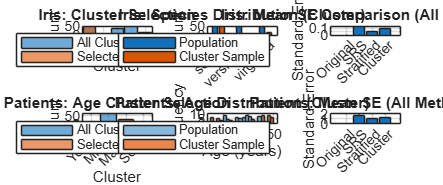


figure('Position', [100 100 1200 500]);

subplot(2,3,1)
histogram(categorical(iris.Cluster)); hold on;
histogram(categorical(iris_cluster.Cluster));
title('Iris: Cluster Selection');
xlabel('Cluster'); ylabel('Count');
legend({'All Clusters','Selected'}); grid on;

subplot(2,3,2)
bar([countcats(iris.Species), countcats(iris_cluster.Species)]);
legend({'Population','Cluster Sample'});
title('Iris: Species Distribution (Cluster)');
xticklabels(species_categories); ylabel('Count'); grid on;

subplot(2,3,3)
se_all_methods = [iris_original_metrics.SE_Mean; 
                  iris_srs_metrics.SE_Mean; 
                  iris_stratified_metrics.SE_Mean;
                  iris_cluster_metrics.SE_Mean];
bar(se_all_methods);
title('Iris: Mean SE Comparison (All Methods)');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Standard Error'); xtickangle(45); grid on;

subplot(2,3,4)
histogram(categorical(patients_data.AgeCluster)); hold on;
histogram(categorical(patients_cluster.AgeCluster));
title('Patients: Age Cluster Selection');
xlabel('Cluster'); ylabel('Count');
legend({'All Clusters','Selected'}); xtickangle(45); grid on;

subplot(2,3,5)
histogram(patients_data.Age, 20, 'FaceAlpha', 0.5); hold on;
histogram(patients_cluster.Age, 20, 'FaceAlpha', 0.7);
title('Patients: Age Distribution (Cluster)');
xlabel('Age (years)'); ylabel('Frequency');
legend({'Population','Cluster Sample'}); grid on;

subplot(2,3,6)
se_all_methods_p = [patients_original_metrics.SE_Mean; 
                    patients_srs_metrics.SE_Mean; 
                    patients_stratified_metrics.SE_Mean;
                    patients_cluster_metrics.SE_Mean];
bar(se_all_methods_p);
title('Patients: Mean SE (All Methods)');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Standard Error'); xtickangle(45); grid on;

**Built-in MATLAB functions:**

- `fprintf`

- `discretize`

- `arrayfun`

- `sprintf`

- `categories`

- `numel`

- `sum`

- `height`

- `randsample`

- `strjoin`

- `ismember`

- `repmat`

- `figure`

- `histogram`

- `categorical`

- `hold`

- `title`

- `xlabel`

- `ylabel`

- `legend`

- `grid`

- `bar`

- `countcats`

- `xticklabels`

- `xtickangle`

**User-defined functions:**

- `compute_cluster_metrics`

- `display_comparison_table`

- `compute_icc_deff`

## 4.10. Interpreting Your Results

**What to Look For:**

- **Error magnitude relative to SRS:** Expect MAE_cluster ≥ MAE_SRS

- **Coverage gaps:** Which population segments are missing?

- **Cluster characteristics:** Are selected clusters typical or extreme?

- **Variance patterns:** Features with high between-cluster variation show larger errors

- **Sample composition:** Does it represent the full population diversity?

**Success Indicators:**

✓ **MAE within acceptable bounds** for your application

✓ **Selected clusters span population characteristics**

✓ **Key subgroups represented** (even if not proportionally)

✓ **Errors consistent with expected DEFF**

✓ **Cost savings justify statistical efficiency loss**

**Red Flags:**

- **Extreme bias in estimates** → Selected clusters highly atypical

- **Missing critical subgroups entirely** → Too few clusters selected

- **Variance much higher than expected** → ICC underestimated, clusters too homogeneous within

- **One cluster dominates** → Cluster size imbalance, consider PPS

- **No improvement in MAE despite cost savings** → May indicate poor cluster definition

## 4.11. Worked example: A complete analysis by hand

## `4.12. `**Key Insights**

**Understanding the efficiency disaster:**

- **High ICC destroys efficiency:** With $\rho  = 0.999$, each additional observation in the same cluster provides almost no new information

- **Few clusters magnify error:** With $c = 2$, we're estimating population from only 2 data points (cluster means)

- **Between-cluster variance is sampling error:** Unlike stratified sampling which eliminates it

**Why this example shows catastrophic failure:**

- **Extreme clustering:** $ICC = 0.999 $(worst case)

- **Minimal cluster selection:** $c = 2 $out of $C = 5$ (40% chance of missing any given cluster)

- **Large clusters:** $m = 40 $(magnifies DEFF)

- **Poor cluster definition:** Clustering by outcome variable creates homogeneity

**Comparing to other methods (for same feature):**


$$n= \frac{80-45}{45}\times 100
= \frac{35}{45}\times 100
= 77.777\% \approx 78\%$$



$$SE= \frac{\text{SE}_{\text{Cluster}}}{\text{SE}_{\text{SRS}}}
= \frac{5.462}{0.225}
= 24.275\ldots \approx 24\times$$


Cluster sampling with 78% more data performs 24× worse than SRS!

**When cluster sampling can work:**

- Clusters are heterogeneous within (each is a "mini-population")

- Low ICC ($\rho  < 0.05$)

- Many clusters selected ($c \ge  30$)

- Small cluster sizes ($m < 20$)

- Massive cost savings justify efficiency loss

**When cluster sampling fails (as in this example):**

- Clusters homogeneous within, heterogeneous between (high ICC)

- Few clusters selected

- Large cluster sizes

- Clustering variable correlates with outcome

**Economic justification:** Cluster sampling only makes sense when: $$$\frac{\text{Cost}{SRS}}{\text{Cost}{Cluster}} > \text{DEFF}$$$

Example: If cluster sampling costs $1/10$ of SRS but DEFF = 40, it's NOT economically justified (would need cost ratio > 40).

**Key Takeaways:**

- Cluster sampling increases variance due to between-cluster heterogeneity

- ICC quantifies clustering effect; high ICC (>0.1) severely reduces efficiency

- Design Effect (DEFF > 1) shows efficiency loss relative to SRS

- SE depends on number of clusters (c), not total observations (n)

- Few clusters + high ICC = catastrophic precision loss

- For Iris clustered by petal length: DEFF ≈ 40, efficiency only 2.5% of SRS

- Only justified when massive cost savings outweigh statistical inefficiency

- Opposite of stratified sampling: high between-group variance is BAD, not good

- Must balance practical feasibility against statistical precision requirements

## 4.13. Practical Recommendations

When to Use Cluster Sampling:

✓ **High travel/access costs** for dispersed individuals

✓ **Natural clustering** in data structure

✓ **No individual sampling frame** available

✓ **Hierarchical data** where context matters

✓ **Federated learning** scenarios with privacy constraints

✓ **Multi-site studies** with institutional cooperation

✓ **Budget constraints** dominate precision requirements

**When to Avoid Cluster Sampling:**

✗ Clusters highly heterogeneous between, homogeneous within

✗ High ICC indicates large design effect

✗ Precision is critical and budget allows alternatives

✗ Individual sampling frame available at low cost

✗ Small number of clusters in population (< 20)

✗ Subgroup precision required (use stratified instead)

**Design Decisions:**

**Number of clusters to select:**

- Minimum: 15-20 for reasonable estimates

- Ideal: 30-50 for stable variance estimation

- More clusters → better estimates, higher costs

**Cluster size considerations:**

- Smaller clusters preferred (lower DEFF)

- Equal-sized clusters simplify analysis

- Very large clusters may dominate estimates

**Stratification of clusters:**

- Always consider stratifying clusters

- Reduces risk of unrepresentative selection

- Minimal additional complexity

## Comparison: Stratified vs. Cluster Sampling

Structural Opposites

**When to Use Which**

**Use stratified when:**

- Groups differ systematically

- Want guaranteed representation

- Have population stratification data

- Statistical efficiency is priority

- Individual sampling is feasible

**Use cluster when:**

- Cost of dispersed sampling prohibitive

- Natural clusters exist

- No individual sampling frame

- Economic efficiency is priority

- Hierarchical data structure

**Can combine:**

- Stratify clusters, then select within strata

- Two-stage: cluster then stratified within clusters

- Complex designs for large surveys

**Key Takeaways:**

- Cluster sampling trades statistical efficiency for economic efficiency

- Design effect typically > 1, meaning less precise than SRS

- Critical when sampling frame exists at cluster level only

- Natural fit for federated learning and distributed AI

- Justified when cost savings outweigh precision loss

- Select enough clusters (30+) for stable estimates

# Section 5: Comparing the Sampling Techniques

%% SECTION 5: Comprehensive Comparison
fprintf('\n\n========================================\n');

fprintf('SECTION 5: COMPREHENSIVE COMPARISON\n');

SECTION 5: COMPREHENSIVE COMPARISON


fprintf('========================================\n\n');


%%% 5.1 Iris Dataset - Complete Comparison
fprintf('--- IRIS DATASET: Complete Method Comparison ---\n\n');

--- IRIS DATASET: Complete Method Comparison ---




fprintf('Standard Error (SE) Comparison:\n');

Standard Error (SE) Comparison:


iris_se_table = table(iris_numeric_vars', ...
    iris_original_metrics.SE, iris_srs_metrics.SE, ...
    iris_stratified_metrics.SE, iris_cluster_metrics.SE, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(iris_se_table);

        Feature        Original      SRS       Stratified    Cluster 
    _______________    ________    ________    __________    ________

    {'SepalLength'}       0         0.10989     0.066641     0.098496
    {'SepalWidth' }       0        0.063147     0.047981     0.037694
    {'PetalLength'}       0         0.23652     0.043022      0.18989
    {'PetalWidth' }       0           0.102      0.02523     0.075281




fprintf('\nMargin of Error (MOE) Comparison:\n');


Margin of Error (MOE) Comparison:


iris_moe_table = table(iris_numeric_vars', ...
    iris_original_metrics.MOE, iris_srs_metrics.MOE, ...
    iris_stratified_metrics.MOE, iris_cluster_metrics.MOE, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(iris_moe_table);

        Feature        Original      SRS      Stratified    Cluster
    _______________    ________    _______    __________    _______

    {'SepalLength'}       0        0.21539      0.13061      1.2515
    {'SepalWidth' }       0        0.12377     0.094042     0.47895
    {'PetalLength'}       0        0.46358     0.084321      2.4128
    {'PetalWidth' }       0        0.19991      0.04945     0.95654




fprintf('\nCoefficient of Variation (CV %%) Comparison:\n');


Coefficient of Variation (CV %) Comparison:


iris_cv_table = table(iris_numeric_vars', ...
    iris_original_metrics.CV, iris_srs_metrics.CV, ...
    iris_stratified_metrics.CV, iris_cluster_metrics.CV, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(iris_cv_table);

        Feature        Original     SRS      Stratified    Cluster
    _______________    ________    ______    __________    _______

    {'SepalLength'}     14.171     15.019      14.695      18.697 
    {'SepalWidth' }     14.256     15.899      13.825      11.652 
    {'PetalLength'}     46.974      51.72      47.537      80.543 
    {'PetalWidth' }     63.555     68.532      63.602      123.26 




fprintf('\nAggregated Summary (Mean across features):\n');


Aggregated Summary (Mean across features):


iris_summary = table({'SE'; 'MOE'; 'CV'}, ...
    [iris_original_metrics.SE_Mean; iris_original_metrics.MOE_Mean; iris_original_metrics.CV_Mean], ...
    [iris_srs_metrics.SE_Mean; iris_srs_metrics.MOE_Mean; iris_srs_metrics.CV_Mean], ...
    [iris_stratified_metrics.SE_Mean; iris_stratified_metrics.MOE_Mean; iris_stratified_metrics.CV_Mean], ...
    [iris_cluster_metrics.SE_Mean; iris_cluster_metrics.MOE_Mean; iris_cluster_metrics.CV_Mean], ...
    'VariableNames', {'Metric','Original','SRS','Stratified','Cluster'});
disp(iris_summary);

    Metric     Original      SRS      Stratified    Cluster
    _______    ________    _______    __________    _______

    {'SE' }          0     0.12789     0.045718     0.10034
    {'MOE'}          0     0.25066     0.089606      1.2749
    {'CV' }     34.739      37.793       34.915      58.539



%%% 5.2 Patients Dataset - Complete Comparison
fprintf('\n\n--- PATIENTS DATASET: Complete Method Comparison ---\n\n');



--- PATIENTS DATASET: Complete Method Comparison ---




fprintf('Standard Error (SE) Comparison:\n');

Standard Error (SE) Comparison:


patients_se_table = table(patients_numeric_vars', ...
    patients_original_metrics.SE, patients_srs_metrics.SE, ...
    patients_stratified_metrics.SE, patients_cluster_metrics.SE, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(patients_se_table);

       Feature       Original      SRS      Stratified    Cluster
    _____________    ________    _______    __________    _______

    {'Age'      }       0         1.2615      1.2712       1.2728
    {'Height'   }       0        0.51846     0.31991      0.33254
    {'Weight'   }       0         3.9893      1.5941       3.2887
    {'Systolic' }       0         1.5092      1.0654      0.85765
    {'Diastolic'}       0         1.0654       1.206      0.93245




fprintf('\nMargin of Error (MOE) Comparison:\n');


Margin of Error (MOE) Comparison:


patients_moe_table = table(patients_numeric_vars', ...
    patients_original_metrics.MOE, patients_srs_metrics.MOE, ...
    patients_stratified_metrics.MOE, patients_cluster_metrics.MOE, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(patients_moe_table);

       Feature       Original     SRS      Stratified    Cluster
    _____________    ________    ______    __________    _______

    {'Age'      }       0        2.6035      2.6235      16.172 
    {'Height'   }       0          1.07     0.66027      4.2254 
    {'Weight'   }       0        8.2336        3.29      41.787 
    {'Systolic' }       0        3.1148      2.1988      10.898 
    {'Diastolic'}       0        2.1988      2.4891      11.848 




fprintf('\nCoefficient of Variation (CV %%) Comparison:\n');


Coefficient of Variation (CV %) Comparison:


patients_cv_table = table(patients_numeric_vars', ...
    patients_original_metrics.CV, patients_srs_metrics.CV, ...
    patients_stratified_metrics.CV, patients_cluster_metrics.CV, ...
    'VariableNames', {'Feature','Original','SRS','Stratified','Cluster'});
disp(patients_cv_table);

       Feature       Original     SRS      Stratified    Cluster
    _____________    ________    ______    __________    _______

    {'Age'      }     18.849     19.536      19.277       25.79 
    {'Height'   }     4.2291     4.5162      3.9787       3.949 
    {'Weight'   }     17.254     15.815      18.257      17.274 
    {'Systolic' }     5.4674     7.1165       5.124      5.5236 
    {'Diastolic'}     8.3564     7.3752      8.9973      9.1152 




fprintf('\nAggregated Summary (Mean across features):\n');


Aggregated Summary (Mean across features):


patients_summary = table({'SE'; 'MOE'; 'CV'}, ...
    [patients_original_metrics.SE_Mean; patients_original_metrics.MOE_Mean; patients_original_metrics.CV_Mean], ...
    [patients_srs_metrics.SE_Mean; patients_srs_metrics.MOE_Mean; patients_srs_metrics.CV_Mean], ...
    [patients_stratified_metrics.SE_Mean; patients_stratified_metrics.MOE_Mean; patients_stratified_metrics.CV_Mean], ...
    [patients_cluster_metrics.SE_Mean; patients_cluster_metrics.MOE_Mean; patients_cluster_metrics.CV_Mean], ...
    'VariableNames', {'Metric','Original','SRS','Stratified','Cluster'});
disp(patients_summary);

    Metric     Original     SRS      Stratified    Cluster
    _______    ________    ______    __________    _______

    {'SE' }          0     1.6688      1.0913      1.3368 
    {'MOE'}          0     3.4442      2.2523      16.986 
    {'CV' }     10.831     10.872      11.127       12.33 



%%% 5.3 Visual Comparison
fprintf('\n--- Creating Comprehensive Comparison Visualizations ---\n');


--- Creating Comprehensive Comparison Visualizations ---


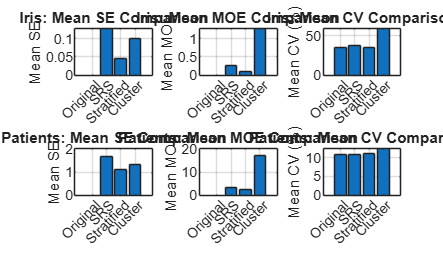


figure('Position', [100 100 1400 800]);

subplot(2,3,1)
bar([iris_original_metrics.SE_Mean, iris_srs_metrics.SE_Mean, ...
     iris_stratified_metrics.SE_Mean, iris_cluster_metrics.SE_Mean]);
title('Iris: Mean SE Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean SE'); xtickangle(45); grid on;

subplot(2,3,2)
bar([iris_original_metrics.MOE_Mean, iris_srs_metrics.MOE_Mean, ...
     iris_stratified_metrics.MOE_Mean, iris_cluster_metrics.MOE_Mean]);
title('Iris: Mean MOE Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean MOE'); xtickangle(45); grid on;

subplot(2,3,3)
bar([iris_original_metrics.CV_Mean, iris_srs_metrics.CV_Mean, ...
     iris_stratified_metrics.CV_Mean, iris_cluster_metrics.CV_Mean]);
title('Iris: Mean CV Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean CV (%)'); xtickangle(45); grid on;

subplot(2,3,4)
bar([patients_original_metrics.SE_Mean, patients_srs_metrics.SE_Mean, ...
     patients_stratified_metrics.SE_Mean, patients_cluster_metrics.SE_Mean]);
title('Patients: Mean SE Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean SE'); xtickangle(45); grid on;

subplot(2,3,5)
bar([patients_original_metrics.MOE_Mean, patients_srs_metrics.MOE_Mean, ...
     patients_stratified_metrics.MOE_Mean, patients_cluster_metrics.MOE_Mean]);
title('Patients: Mean MOE Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean MOE'); xtickangle(45); grid on;

subplot(2,3,6)
bar([patients_original_metrics.CV_Mean, patients_srs_metrics.CV_Mean, ...
     patients_stratified_metrics.CV_Mean, patients_cluster_metrics.CV_Mean]);
title('Patients: Mean CV Comparison');
xticklabels({'Original','SRS','Stratified','Cluster'});
ylabel('Mean CV (%)'); xtickangle(45); grid on;

%%% 5.4 Key Findings Summary
fprintf('\n--- KEY FINDINGS SUMMARY ---\n\n');


--- KEY FINDINGS SUMMARY ---




fprintf('IRIS DATASET:\n');

IRIS DATASET:


fprintf('  Best SE: Stratified (%.4f) - %.1f%% better than SRS\n', ...
    iris_stratified_metrics.SE_Mean, ...
    100*(iris_srs_metrics.SE_Mean - iris_stratified_metrics.SE_Mean)/iris_srs_metrics.SE_Mean);

  Best SE: Stratified (0.0457) - 64.3% better than SRS


fprintf('  Worst SE: Cluster (%.4f) - %.1f%% worse than SRS\n', ...
    iris_cluster_metrics.SE_Mean, ...
    100*(iris_cluster_metrics.SE_Mean - iris_srs_metrics.SE_Mean)/iris_srs_metrics.SE_Mean);

  Worst SE: Cluster (0.1003) - -21.5% worse than SRS



fprintf('\nPATIENTS DATASET:\n');


PATIENTS DATASET:


fprintf('  Best SE: Stratified (%.4f) - %.1f%% better than SRS\n', ...
    patients_stratified_metrics.SE_Mean, ...
    100*(patients_srs_metrics.SE_Mean - patients_stratified_metrics.SE_Mean)/patients_srs_metrics.SE_Mean);

  Best SE: Stratified (1.0913) - 34.6% better than SRS


fprintf('  Worst SE: Cluster (%.4f) - %.1f%% worse than SRS\n', ...
    patients_cluster_metrics.SE_Mean, ...
    100*(patients_cluster_metrics.SE_Mean - patients_srs_metrics.SE_Mean)/patients_srs_metrics.SE_Mean);

  Worst SE: Cluster (1.3368) - -19.9% worse than SRS



fprintf('\n========================================\n');

fprintf('TUTORIAL COMPLETE\n');

TUTORIAL COMPLETE


fprintf('========================================\n');

Helper functions are MATLAB® functions that you define to use in across the workbook. After you define a helper function, you can call it at different places in your code. This increases reusability. For example, you can call a helper function to calculate the SE and MOE multiple times while writing the code only once.

%% HELPER FUNCTIONS

function se = compute_se(data, pop_size, sample_size)
    variance = var(data);
    fpc = sqrt((pop_size - sample_size) / pop_size);
    se = sqrt(variance / sample_size) * fpc;
end

function moe = compute_moe(se, sample_size, confidence_level)
    alpha = 1 - confidence_level;
    
    if sample_size >= 30
        z_critical = norminv(1 - alpha/2);
        moe = z_critical * se;
    else
        df = sample_size - 1;
        t_critical = tinv(1 - alpha/2, df);
        moe = t_critical * se;
    end
end

function cv = compute_cv(data)
    data_mean = mean(data);
    data_std = std(data);
    cv = (data_std / data_mean) * 100;
end

function metrics = compute_dataset_metrics(dataset, var_names, pop_size, sample_size, confidence_level)
    num_vars = numel(var_names);
    se_values = zeros(num_vars, 1);
    moe_values = zeros(num_vars, 1);
    cv_values = zeros(num_vars, 1);
    
    for i = 1:num_vars
        var_data = dataset.(var_names{i});
        se_values(i) = compute_se(var_data, pop_size, sample_size);
        moe_values(i) = compute_moe(se_values(i), sample_size, confidence_level);
        cv_values(i) = compute_cv(var_data);
    end
    
    metrics.SE = se_values;
    metrics.MOE = moe_values;
    metrics.CV = cv_values;
    metrics.SE_Mean = mean(se_values);
    metrics.MOE_Mean = mean(moe_values);
    metrics.CV_Mean = mean(cv_values);
    metrics.VarNames = var_names;
end

function metrics = compute_stratified_metrics(pop_data, sample_data, var_names, strat_var, confidence_level)
    num_vars = numel(var_names);
    se_values = zeros(num_vars, 1);
    
    strata = categories(pop_data.(strat_var));
    num_strata = numel(strata);
    
    for i = 1:num_vars
        var_name = var_names{i};
        se_squared = 0;
        
        for h = 1:num_strata
            stratum = strata{h};
            
            pop_stratum = pop_data(pop_data.(strat_var) == stratum, :);
            N_h = height(pop_stratum);
            W_h = N_h / height(pop_data);
            
            sample_stratum = sample_data(sample_data.(strat_var) == stratum, :);
            n_h = height(sample_stratum);
            
            if n_h > 0
                s_h_squared = var(sample_stratum.(var_name));
                fpc = (N_h - n_h) / N_h;
                se_squared = se_squared + (W_h^2) * (s_h_squared / n_h) * fpc;
            end
        end
        
        se_values(i) = sqrt(se_squared);
    end
    
    sample_size = height(sample_data);
    moe_values = zeros(num_vars, 1);
    cv_values = zeros(num_vars, 1);
    
    for i = 1:num_vars
        moe_values(i) = compute_moe(se_values(i), sample_size, confidence_level);
        cv_values(i) = compute_cv(sample_data.(var_names{i}));
    end
    
    metrics.SE = se_values;
    metrics.MOE = moe_values;
    metrics.CV = cv_values;
    metrics.SE_Mean = mean(se_values);
    metrics.MOE_Mean = mean(moe_values);
    metrics.CV_Mean = mean(cv_values);
    metrics.VarNames = var_names;
end

function metrics = compute_cluster_metrics(pop_data, sample_data, var_names, num_clusters_selected, confidence_level)
    num_vars = numel(var_names);
    se_values = zeros(num_vars, 1);
    moe_values = zeros(num_vars, 1);
    cv_values = zeros(num_vars, 1);
    
    sample_size = height(sample_data);
    
    for i = 1:num_vars
        var_data = sample_data.(var_names{i});
        
        se_values(i) = compute_se(var_data, height(pop_data), sample_size);
        
        alpha = 1 - confidence_level;
        df = num_clusters_selected - 1;
        if df > 0
            t_critical = tinv(1 - alpha/2, df);
            moe_values(i) = t_critical * se_values(i);
        else
            moe_values(i) = NaN;
        end
        
        cv_values(i) = compute_cv(var_data);
    end
    
    metrics.SE = se_values;
    metrics.MOE = moe_values;
    metrics.CV = cv_values;
    metrics.SE_Mean = mean(se_values);
    metrics.MOE_Mean = mean(moe_values);
    metrics.CV_Mean = mean(cv_values);
    metrics.VarNames = var_names;
end

function [icc, deff] = compute_icc_deff(data, selected_clusters, cluster_var, sample_var)
    cluster_data = data(ismember(data.(cluster_var), selected_clusters), :);
    
    cluster_means = zeros(numel(selected_clusters), 1);
    cluster_sizes = zeros(numel(selected_clusters), 1);
    
    for i = 1:numel(selected_clusters)
        cluster_subset = cluster_data(cluster_data.(cluster_var) == selected_clusters{i}, :);
        cluster_means(i) = mean(cluster_subset.(sample_var));
        cluster_sizes(i) = height(cluster_subset);
    end
    
    var_between = var(cluster_means);
    
    var_within = 0;
    for i = 1:numel(selected_clusters)
        cluster_subset = cluster_data(cluster_data.(cluster_var) == selected_clusters{i}, :);
        if height(cluster_subset) > 1
            var_within = var_within + sum((cluster_subset.(sample_var) - cluster_means(i)).^2);
        end
    end
    var_within = var_within / (height(cluster_data) - numel(selected_clusters));
    
    if (var_between + var_within) > 0
        icc = var_between / (var_between + var_within);
    else
        icc = 0;
    end
    
    avg_cluster_size = mean(cluster_sizes);
    deff = 1 + (avg_cluster_size - 1) * icc;
end

function display_metrics_table(metrics, title_str)
    fprintf('\n%s:\n', title_str);
    fprintf('%-15s %12s %12s %12s\n', 'Variable', 'SE', 'MOE', 'CV (%)');
    fprintf('%s\n', repmat('-', 1, 55));
    
    for i = 1:numel(metrics.VarNames)
        fprintf('%-15s %12.4f %12.4f %12.2f\n', ...
            metrics.VarNames{i}, metrics.SE(i), metrics.MOE(i), metrics.CV(i));
    end
    
    fprintf('%s\n', repmat('-', 1, 55));
    fprintf('%-15s %12.4f %12.4f %12.2f\n', ...
        'MEAN', metrics.SE_Mean, metrics.MOE_Mean, metrics.CV_Mean);
end

function display_comparison_table(metrics1, metrics2, label1, label2)
    fprintf('\n%-15s | %s (SE/MOE/CV) | %s (SE/MOE/CV)\n', ...
        'Variable', label1, label2);
    fprintf('%s\n', repmat('-', 1, 80));
    
    for i = 1:numel(metrics1.VarNames)
        fprintf('%-15s | %5.4f / %5.4f / %5.1f | %5.4f / %5.4f / %5.1f\n', ...
            metrics1.VarNames{i}, ...
            metrics1.SE(i), metrics1.MOE(i), metrics1.CV(i), ...
            metrics2.SE(i), metrics2.MOE(i), metrics2.CV(i));
    end
    
    fprintf('%s\n', repmat('-', 1, 80));
    fprintf('%-15s | %5.4f / %5.4f / %5.1f | %5.4f / %5.4f / %5.1f\n', ...
        'MEAN', ...
        metrics1.SE_Mean, metrics1.MOE_Mean, metrics1.CV_Mean, ...
        metrics2.SE_Mean, metrics2.MOE_Mean, metrics2.CV_Mean);
end